# Logistic map

[https://www.mathworks.com/help/symbolic/sym.expand.html](https://www.mathworks.com/help/symbolic/sym.expand.html)

[https://www.mathworks.com/help/symbolic/solve.html](https://www.mathworks.com/help/symbolic/solve.html)

[https://www.mathworks.com/help/symbolic/simplify-symbolic-expressions.html](https://www.mathworks.com/help/symbolic/simplify-symbolic-expressions.html)

[https://www.mathworks.com/help/symbolic/create-symbolic-functions.html](https://www.mathworks.com/help/symbolic/create-symbolic-functions.html)

g=@(x,a) a.*x.*(1-x)

g = function_handle with value:
    @(x,a)a.*x.*(1-x)


f=@(x,a) a.*x^2+(1-a).*x

f = function_handle with value:
    @(x,a)a.*x^2+(1-a).*x


syms x a
expand(x-g(x,a))

$$ans = x-a\,x+a\,x^{2}$$

expand(f(x,a))

$$ans = x-a\,x+a\,x^{2}$$

Logistic map has two fixed points:

equation=x==g(x,a)

$$equation = x=-a\,x\,\left(x-1\right)$$

S=solve(equation)

$$S = \left(\begin{array}{c} 0\\ \frac{a-1}{a} \end{array}\right)$$

S(1)

$$ans = 0$$

S(2)

$$ans = \frac{a-1}{a}$$

To determin their stability we need to compute derivatives:

syms derivative(x,a)
derivative(x,a)=diff(g(x,a),x)

$$derivative(x, a) = -a\,x-a\,\left(x-1\right)$$

d(1)=derivative(S(1),a);
d(2)=simplify(derivative(S(2),a));
d

$$d = \left(\begin{array}{cc} a & 2-a \end{array}\right)$$

The stability of the fixed points is given by the following inequalities:

abs(d(1))<1

$$ans = \left|a\right|<1$$

abs(d(2))<1

$$ans = \left|a-2\right|<1$$

**Cobweb plot**

[https://en.wikipedia.org/wiki/Cobweb_plot](https://en.wikipedia.org/wiki/Cobweb_plot)

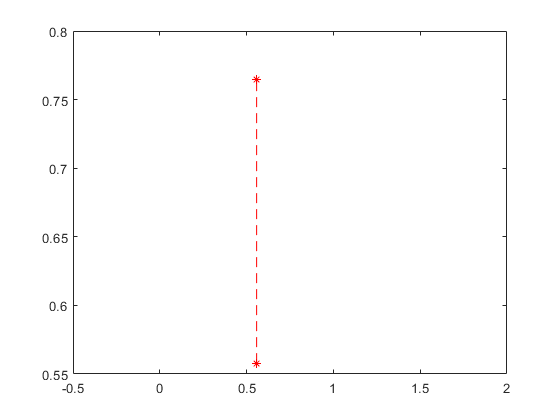

a=3.1;x=0.5;
xx=linspace(0,1,1000);
set(gcf,'Visible','on')
plot(xx,g(xx,a),xx,xx)
hold on
gx=g(x,a);
plot(x,gx,'r*')
pause(0.5)
for k=1:20
    plot([x,gx],[gx,gx],'r--*')
    pause(0.5)
    x=gx;gx=g(x,a);
    plot([x,x],[x,gx],'r--*')
    pause(0.5)
end
hold off